clc;
clear all;

# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 14-Sep-2021 09:52:08

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([32 32 1],"Name","imageinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],64,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],128,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],128,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],256,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_2")
    convolution2dLayer([3 3],128,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_9")
    convolution2dLayer([3 3],128,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")
    reluLayer("Name","relu_10")
    transposedConv2dLayer([3 3],64,"Name","transposed-conv_2","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(3,2,"Name","concat_1")
    convolution2dLayer([3 3],64,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_12")
    convolution2dLayer([3 3],64,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")
    reluLayer("Name","relu_13")
    convolution2dLayer([1 1],1,"Name","conv_12","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput","conv_1");
lgraph = connectLayers(lgraph,"imageinput","addition/in1");
lgraph = connectLayers(lgraph,"relu_3","maxpool_1");
lgraph = connectLayers(lgraph,"relu_3","concat_1/in1");
lgraph = connectLayers(lgraph,"relu_5","maxpool_2");
lgraph = connectLayers(lgraph,"relu_5","concat_2/in1");
lgraph = connectLayers(lgraph,"relu_8","concat_2/in2");
lgraph = connectLayers(lgraph,"relu_11","concat_1/in2");
lgraph = connectLayers(lgraph,"conv_12","addition/in2");

## Plot Layers

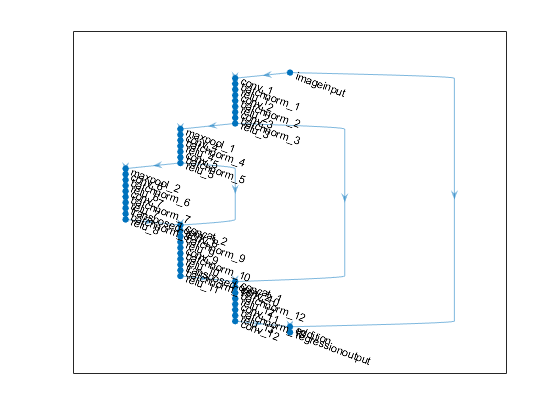

plot(lgraph);